# Unit 7. Performance issues: memory

## Learning about availability of memory

The following chapter assumes that you have exhausted all programming techniques for making the best of the computer memory that is available (consult help by the MathWorks: search the documentation for 'Resolve "Out of Memory" Errors' which is also available online. In that document you will find a number of programming techniques to maximize memory).

% how to find out about the amount of memory at
% our disposition? In matlab version 7.6 and up,
% this will give you an overview of memory
% availability
memory
mem=memory
% so, the memory available for all arrays in bytes 
% is
mem.MemAvailableAllArrays
% ..or in megabytes
mem.MemAvailableAllArrays/2^20
% In matlab, any variable must fit into a
% contiguous block of memory. So, before trying to
% generate a huge variable you can check whether
% it will fit into the workspace. Let's check 
% whether a square double array of n^2 elements
% will fit. We need to query the value of field
% MaxPossibleArrayBytes:
mem.MaxPossibleArrayBytes
n=5000;
if n^2*8<=mem.MaxPossibleArrayBytes
  disp(['a ' int2str(n) ' by ' int2str(n) ' array should be fine']);
end

% in case you deal with versions 7.0 to 7.5, in
% which function memory does not exist, use the
% 'feature' function
feature('MemStats')
% the command 
%              m=feature('DumpMem')
% will put out the largest available memory 
% block in bytes (we won't run it here because 
% its output runs to several pages)


## Consolidating memory

Find that a large variable does not fit into memory although the amount of RAM suggests it should? Particularly after an extended computing session the most likely cause is memory fragmentation (yes, even when you cleared all variables from the workspace the memory allocated to Matlab remains fragmented). 

We have two options for an immediate remedy:

1. The pack command. It is a memory defragmenter and may help in some cases. However, you have to run it 'manually' from the command line (running it in this script is futile) and it also has some other snags (see the help).

pack

2. The ultimate means of memory consolidation is also the most obvious: exit Matlab and start a fresh session.

## 'No java' mode

A further, if somewhat inconvenient possibilty:you can start Matlab in 'no java' mode: Exit Matlab. Then right click on the matlab icon. In the text field where sth. like "C:\Program Files\MATLAB\R2017a\bin\matlab.exe" is to be seen, append (with a space in between)

-nojvm

Running matlab in 'no java' mode will reward you with more memory (and potentially faster performance). It is still approved by the MathWorks to do so on Linux and and Mac operating systems, but not on Windows anymore.The reason is that you will have to make do without the matlab text editor and the many useful features of the desktop, as well as common graphics commands (like e.g. get(gca)).

## Datastore objects and tall arrays

If all of the above fails, or you know from the outset that your data will never fit into memory, you may want to use the new features in Matlab paying tribute to the requirements of Big Data: datastore and tall arrays.

% Let's pretend one of our data files were too
% big to fit completely into memory and glimpse at
% the possibilities in Matlab to deal with such
% data: first, make an object of type datastore
ds=datastore('data\lfp.asc','Type','tabulartext')
% and then declare a tall variable:
lfp_tall=tall(ds)

% Note that Matlab automatically started a 'parallel 
% pool' (see below).
% Because the data is arranged in a tabular format
% in file lfp.asc we obtain a tall table as an
% output. We can then perform some computations on
% this table, e.g. convert it to an array and
% compute the standard deviation of the signals
% across time
std_lfp_tall=std(table2array(lfp_tall))

% The output looks a bit odd, though: question
% marks, and what about the Preview being
% deferred? 
% The idea behind tall arrays/tables is that
% you list a range of operations that you'd like
% to perform on the data and only once you really
% need them get them via gather:
std_lfp=gather(std_lfp_tall)
% This way, Matlab can perform operations on data
% which are too large to be held in memory, and
% provides you with the output (which has to fit
% into memory if gathered).

% We can use tall variables directly with a growing 
% arsenal of functions, including graphics functions, 
% but use common sense. For example, while the plot 
% function may be used, think beforehand about the 
% gains vs. cost of plotting myriads of data points.
% For visualization it may make more sense to generate 
% e.g. a histogram
histogram(lfp_tall{:,1})

% Final note: the operations on the lfp data are
% ridiculously slow because a lot of overhead is
% involved in dealing with tall arrays. Use them
% only if you need to.

clear
delete(gcp('nocreate'))

## Working on outdated hardware?

The following is only relevant if you are stuck with a 32-bit computer/Matlab version of the windows operating system: you will still run out of memory on such a system if the size of your variables approaches 2 GB, no matter how much RAM is installed. The reason is that any 'process' (read: program) in windows will only be allotted 2 GB of RAM; subtracting a few hundred MB for Matlab itself we arrive at < 2 GB. If that is the case search the MathWorks website for

/3 GB

which produces documents explaining the usage of the /3 GB switch on the various windows platforms. For reasons explained there the maximally possible size of variables will not increase (much), but at least the total memory available (guess to what amount). It goes without saying that your computer must have more than 3 GB of RAM for the trick to work. Also, exert caution - some systems react adversely to this option.

# Performance issues: efficiency and parallelization of computations

## Statement of the problem: concrete example

We would like to generate so-called surrogate data from an EEG recording from a rat. Compared to the original time series, surrogate data have a very similar amplitude distribution and spectral power, but randomized phases. They are often used for statistical analysis, e.g. in the neurosciences to verify instances of cross-frequency coupling as evident in hippocampus:

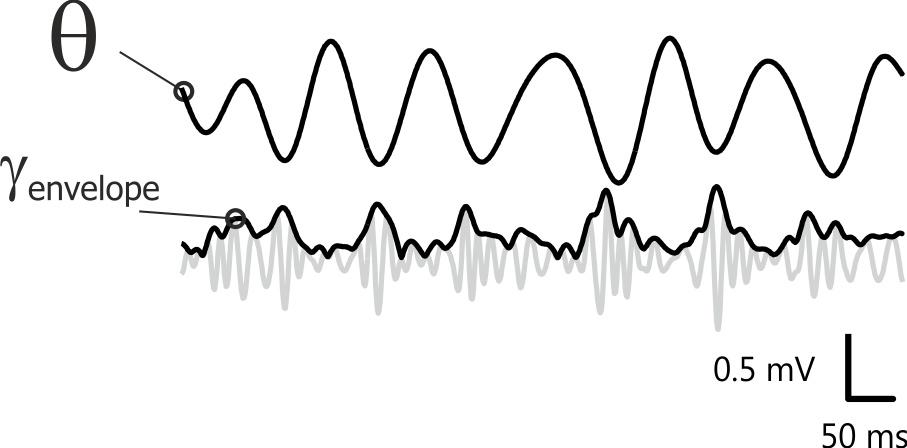

The generation of surrogate data can be computationally costly, involving multiple rounds of Fourier transforms and inverse Fourier transforms for each instance, so this is certainly an area of scientific computation that will benefit from optimization of computational efficiency.

Let's first load the EEG data

edit surrdat
% Preparations:
% - load EEG data (~1200 s recorded at 2000 Hz,
% one channel)
m=matfile('data\proj_timeSeriesAnalysis\wrat04_enf0004.mat');
d=m.d(1:1e6,1);
% - sampling frequency in Hz (inverse of sampling
% interval)
fs=1e6/m.si;
% - what have we got?
whos
figure(1), clf
excIx=10001:40000;
plot(d(excIx))


To generate surrogate data, we use function surrdat. Let's see how much time it takes and how many of the processor's resources are consumed when we request 50 instances of surrogate data (open the windows task manager or a similar tool on other operating systems)

tic
surrD=surrdat(d,fs,50);
cpuSerialTime_double=toc

% (Re-) plot excerpt of original data and three
% instances of surrogate data
figure(1), clf
plot(d(excIx),'r')
hold on
plot(surrD(excIx,1:3)+repmat([-1 -2 -3]*800,excIx(end)-excIx(1)+1,1),'k');
hold off
axis tight
title('original and surrogate data')

On most computers, the time consumed is sufficient to make us a little itchy (or go get a coffee). Moreover, Matlab is blocked working on the job. Lastly, on CPUs with several cores, the CPU is not maxed out.

We can improve the situation on several counts with various approaches.

## Approach #1: GPU computing

If you have the right hardware (CUDA-enabled NVIDIA GPU with compute capability 2.0 or higher) GPU computing offers potentially ***tremendous gains in computational speed with very little coding effort***. You can verify this with a benchmark test (GPUbench, [http://de.mathworks.com/matlabcentral/fileexchange/34080-gpubench),](http://de.mathworks.com/matlabcentral/fileexchange/34080-gpubench),) which has been run on a computer with the following components:

- CPU: Intel Core i7-4770K (launched early 2013)

- GPU: nvidia GeForce GTX 750 ti (launched early 2014)

Here are the results:

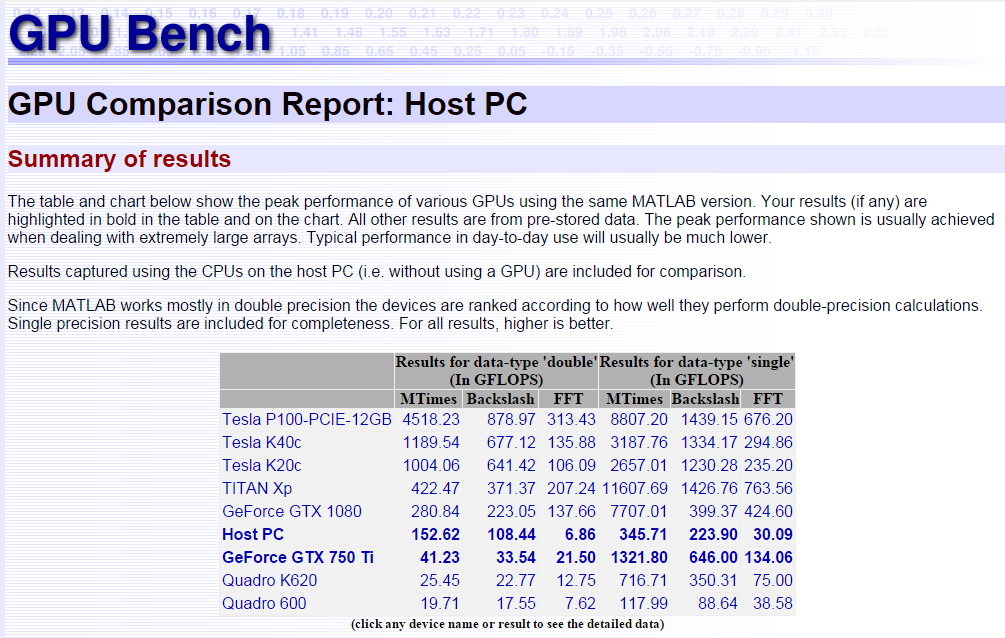

Observations: 

- In the host PC's CPU, computations with single precision run about twice as fast as those with double precision (no surprise here)

- In the GPU, computations with single precision can run** six to thirty** times as fast as those with double precision, easily outperforming the CPU!

**Note: the double-precision compute performance of consumer ('gaming') graphics cards is artificially throttled. **This is not the case in graphics cards sold for the purpose of (scientific) number crunching (compare the chart for e.g. the Tesla K40c).

You can find out whether you have the right hardware (and sufficiently up-to-date driver) by counting the number of GPUs suitable for computation in Matlab:

gpuDeviceCount

Let's now go back to the surrogate data example. First, convert the data to single in order to maximize the gain from having a graphics card, and repeat the CPU computations for reference (all computations now done in 'quiet' mode):

d=single(d);
tic
surrD=surrdat(d,fs,50,true);
cpuSerialTime_single=toc

If we do have a suitable graphics card, we can go ahead and test how long computations on the GPU take (run the section below twice because upon the first run Matlab will have to load some of the GPU computing routines into the GPU's memory, which takes some time):

if gpuDeviceCount>=1
  tic
  d=gpuArray(d);
  surrD=surrdat(d,fs,50,true);
  surrD=gather(surrD);
  gpuTime_single=toc
else
  % load values from different computer
  load data/computeTimes_hh64
end

Compare the performances in terms of computational time:

clf
x=1:3;
bar(x,[cpuSerialTime_double, cpuSerialTime_single, gpuTime_single]);
set(gca,'xtick',x,'xticklabel',{'CPU, double','CPU, single','GPU, single'},...
    'xticklabelrotation',30)
ylabel('compute time (s)')

## Approach #2: explicit parallel computing on the CPU

NOTE: the code in the following paragraphs is pointless if you run it on a computer with a single processor containing only one core because the essence of parallel computing is the engagement of several cores/processors in parallel. Also, your computer should have at least 8 GB of RAM, otherwise you should reduce the number of surrogate instances to avoid running out of memory.

- PARALLEL COMPUTING APPROACH 1:  Running a 'batch' job in the background

% Offload the job to the background using
% 'batch'. Let us run a batch job on a different
% set of data (~1700 s recorded at 2000 Hz, one
% channel)
m=matfile('data\proj_timeSeriesAnalysis\wrat04_halo0006.mat');
d2=m.d(1:1e6,1);
fs2=1e6/m.si;

% Call batch with the name of the function as the
% first input argument, then the number of output
% arguments we expect, then the necessary input
% arguments into the function
job01=batch('surrdat',1,{d2,fs2,50,true});


% After a few seconds, during which Matlab is busy
% offloading the job, we can query the state of
% the batch job with the job monitor or
% programmatically, as here
get(job01,'State')

% ...and continue working in Matlab, e.g. by
% computing power spectra and autocorrelations
% of the first data trace and its surrogate data
% - power spectra:
d=gather(d);
[p,f]=pwelch(d,hamming(2^12),0,2^12,fs);
[surrP]=pwelch(surrD,hamming(2^12),0,2^12,fs);
clf
subplot(2,1,1), hold on
ph1=plot(f,surrP,'k');
ph2=plot(f,p,'m');
axis tight
grid on
set(gca,'xscale','log','yscale','log');
xlabel('frequency (Hz)')
ylabel('power spectral density (µV^2/Hz)')
legend([ph1(1),ph2],{'surr.','real'})
% - autocorrelations:
[xc,lags]=xcorr(d,2000,'coeff');
subplot(2,1,2), hold on
for xci=1:size(d,2)
  [surrXc]=xcorr(surrD(:,xci),2000,'coeff');
  plot(lags,surrXc,'k');
end
plot(lags,xc,'m');
xlabel('lag (points)')
ylabel('correlation')



% After the batch job is done, we have to fetch
% the outputs
get(job01,'State')

batch_output=fetchOutputs(job01);
% See what we've got
whos batch_output

% The output of function surrdat was placed in the
% first element of cell array batch_output
surrD2=batch_output{1};
clear batch_output
% Clear the job
delete(job01)
whos

clear surrD surrD2 


- PARALLEL COMPUTING APPROACH 2: 'parfor' loops

% Begin by initiating a 'pool' of 'workers' which
% are supposed to work in parallel. In doing so,
% assign variable ppool so we can access and
% manipulate our pool of workers:
ppool=parpool;
ppool
ppool.NumWorkers
% By default, the number of workers is identical
% to the number of (physical, not virtual) cores
% of the central processing unit (CPU). You can
% specify a lower number, but for all practical
% purposes let's stick with it.


% Let's start with an examplary parfor code
% provided by the Matworks
edit ex_compare
% ...and run it
ex_compare


% We do in fact see a notably shorter
% computational time. Does this also apply to our
% example of surrogate data computation?
% - sequential version
tic
surrD=surrdat(d,fs,10,true);
toc
% - parallel version
tic
surrD=surrdat_par(d,fs,10);
toc

% Disappointment! The parallel loop takes about the 
% same time or is even slower (depending on the 
% computer specs).
% Let's generate many more instances of surrogate
% data for an excerpt of the data and compare
% sequential and parallel computing again

tic
surrD=surrdat(d(1:2e4),fs,1000,true);
toc

tic
surrD=surrdat_par(d(1:2e4),fs,1000);
toc
% The parallel code is faster, but not by much, at
% least on a computer with only 2 cores. 


*Parallelization with parfor can backfire for a variety of reasons*. Among them:

1. the computational effort of organizing parallel computations (called 'overhead' in computer-speak) can outweigh any gains from running the computations in parallel

2. the functions used may already employ multithreading (=roughly speaking, some kind of built-in mode of engaging CPU cores in parallel), which is hard to beat by explicit parallelization


% A major reason in the specific example above
% is that the functions called within the (par)for
% loops, notably including fft, are built-in and
% multithreaded:
edit fft


% Finally, an example of nontrivial computations
% which benefit substantially from explicit parallel
% processing:
edit example_clustering_parallel
example_clustering_parallel


- PARALLEL COMPUTING APPROACH 3: parfeval

-> See exercise 7.3